# 2PEM-100A

## `PRACTICE 5_1`

## `Energy Consumption Modeling`

`More information:`

- [https://2pem100a.blogspot.com/](https://2pem100a.blogspot.com/)

`More examples:`

- [https://github.com/vasanza/Matlab_Code/tree/Electrical-Systems-Simulation](https://github.com/vasanza/Matlab_Code/tree/Electrical-Systems-Simulation)

- [https://github.com/avbazurt/Simulacion_Sistemas_Electricos](https://github.com/avbazurt/Simulacion_Sistemas_Electricos)

`Dataset:`

- [http://ieee-dataport.org/8630](http://ieee-dataport.org/8630)

Technical information

- Sampling frequency: 4Hz (250mSeg)

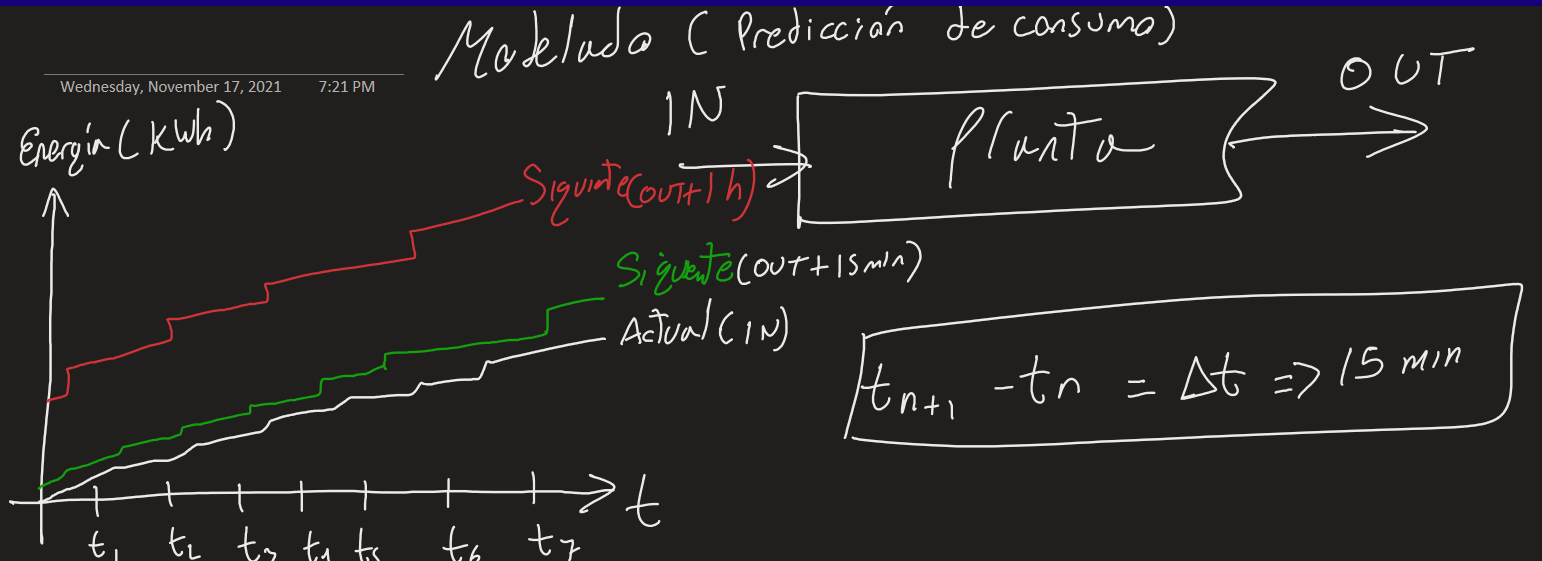

**1- Loading a .mat file with 1sample sampling rate / 15min = 1sample / 900seg**

**Data (451x9), donde 451x15min=6765min/60min=112.75horas/24=4.69dias**

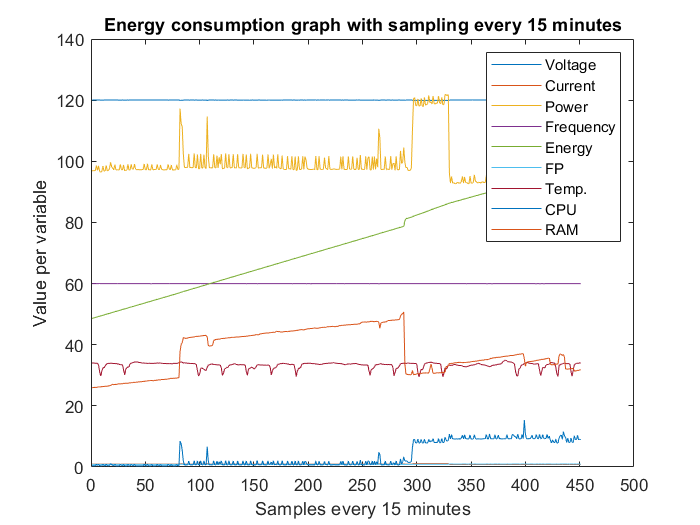

clear;%borra el worskpace
clc;%borra el comand windiw
path=fullfile('./datamean.mat');
data=load(path);
data=struct2cell(data);
data=data{1,1};%table
plot(data);%datos originales
title('Energy consumption graph with sampling every 15 minutes');
legend('Voltage','Current','Power','Frequency','Energy','FP','Temp.','CPU','RAM');

xlabel('Samples every 15 minutes');
ylabel('Value per variable');

**2- Separate variables**

Time=(0:1:length(data)-1)'; %Time Vector
Voltaje=[Time data(:,1)];
Corriente=[Time data(:,2)];
Potencia=[Time data(:,3)];
Frecuencia=[Time data(:,4)];
Energia=[Time data(:,5)];
FP=[Time data(:,6)];
Temp=[Time data(:,7)];
CPU=[Time data(:,8)];
RAM=[Time data(:,9)];

# **Example 1: Generate the input (IN) and output (OUT) data of the model**

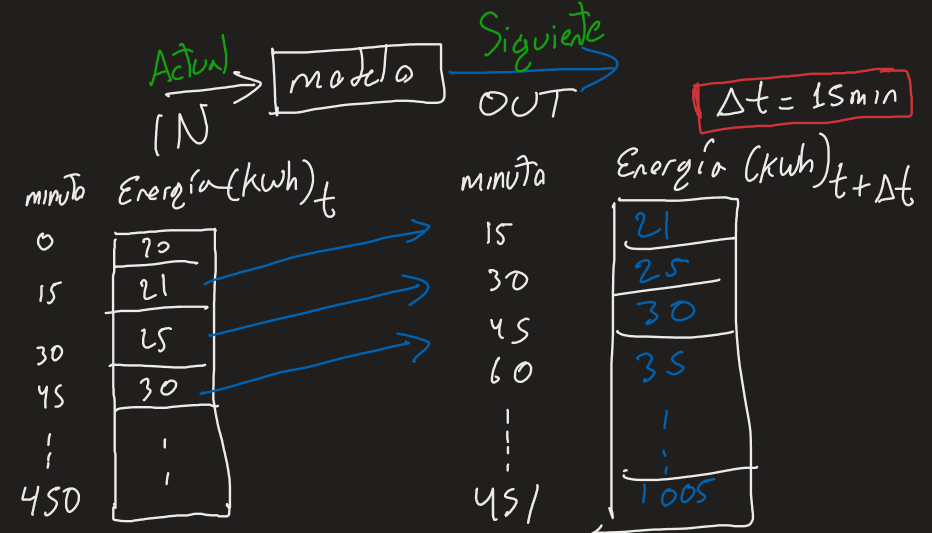

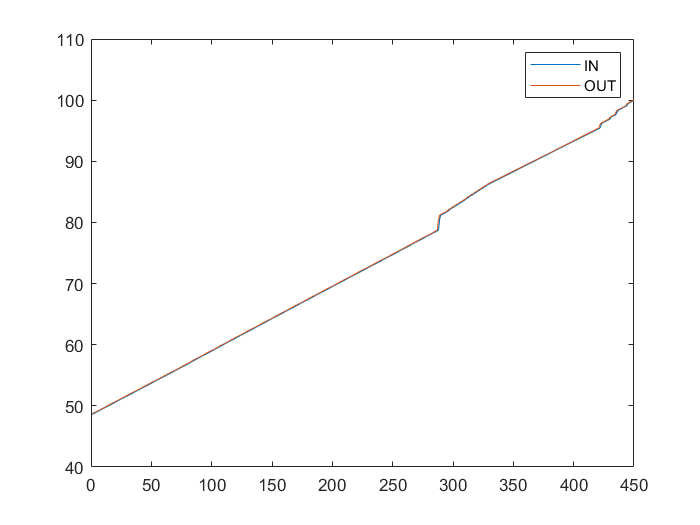

% Fila 1 -> Tiempo, Fila 2 -> Variable
IN=Energia(1:length(Energia)-1,2);%Energía actual (t)
OUT=Energia(2:length(Energia),2);%Energia siguiente (f+dT)
Datos=[IN OUT];

plot(IN);
hold on
plot(OUT);
legend('IN','OUT');

save('Datos.csv','Datos');%Guarda los datos en formato CSV

# **Ejemple 2: Identificacion System Toolbo **

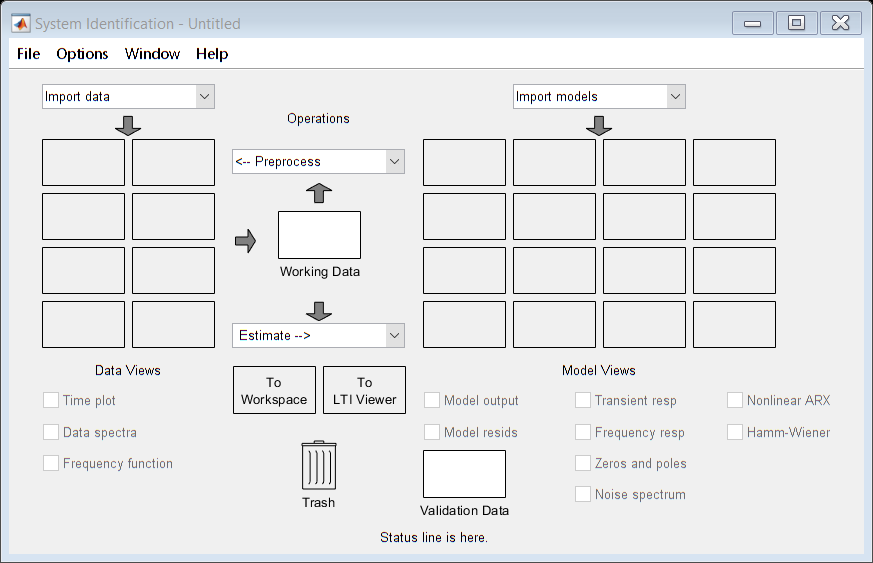

ident

# **Ejemple 3: Energy consumption modeling**

%% Transfer Function obtained (Method 3)
G=tf(d2c(arxqs));%<---Best FIT Model Modelo con mejor FIT
num=cell2mat(G.numerator)

num =     1.2970    0.0060    0.0000    0.0000    0.0000


den=cell2mat(G.denominator)

den =     1.0000    0.0039    0.0000    0.0000    0.0000


FTmotor=tf(num,den)

FTmotor =
 
  1.297 s^4 + 0.006039 s^3 + 1.509e-05 s^2 + 2.036e-08 s + 1.404e-11
  ------------------------------------------------------------------
     s^4 + 0.00394 s^3 + 1.052e-05 s^2 + 1.604e-08 s + 1.403e-11
 
Continuous-time transfer function.



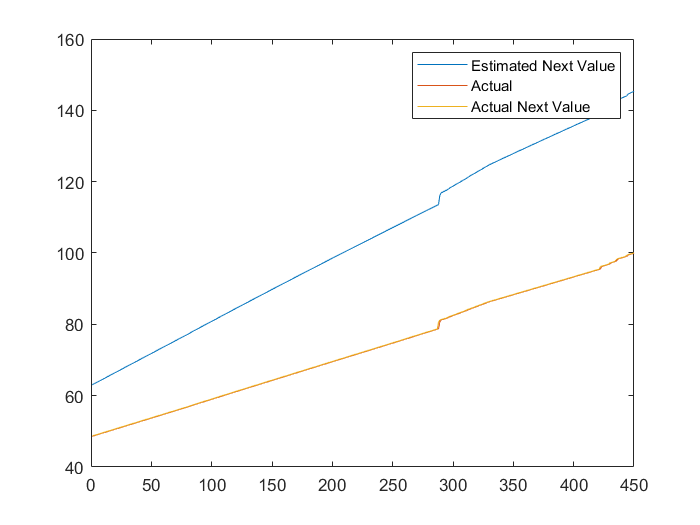

Time=(0:1:length(IN)-1)'; %Vector de tiempo
y = lsim(G,IN,Time); % system response
figure
plot(y);
hold on;
plot(IN);
plot(OUT);
legend('Estimated Next Value', 'Actual', 'Actual Next Value');